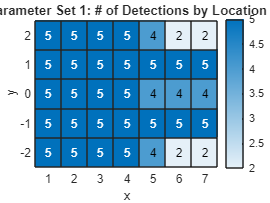

% seimic_detection.mlx
% given 30 seconds of seismic data from the three probes, make a 
% determination about whether a human has been found in the purview
% of the sensor 

% parameters
num_segments = 20;
threshold_time = 0.5;
trigger_slope = 0.4;
num_pt_fit = 7;
time_similarity = 0.7;

detections = zeros(21,1);
detections(20) = 2;
detections(21) = 2;
locations = 1:21;

toa_actual = [3,   7;
              13, 17;
              23, 27];
corr_toa_arr= zeros(21,1);
corr_toa_arr(20) = 0.05;
corr_toa_arr(21) = 0.05;
for location = 1:19
    for trial = 1:5
        filename = sprintf("seismic_loc%i_%i.mat",location,trial);
        filename = fullfile(pwd,'/testing/matfiles',filename);
        %filename = filename.Name;
        % Calculate arrival times
        toa1 = toa_calculate(filename,num_segments,1,trigger_slope,num_pt_fit,time_similarity);
        toa2 = toa_calculate(filename,num_segments,2,trigger_slope,num_pt_fit,time_similarity);
        toa3 = toa_calculate(filename,num_segments,3,trigger_slope,num_pt_fit,time_similarity);
        % % Generate a non-redundant, corroborated set of arrival times
        corr_toa = corroborate_toa(toa1,toa2,toa3,threshold_time);
        % % If more than one element in the array, consider a detection
        detections(location,1) = detections(location,1) + double(~isempty(corr_toa));
    end
    corr_toa_arr(location) = corr_toa_arr(location) / 5;
end

%detections(4) = 5;

% Define the grid size and values
x = 1:7; % Grid along x-axis
y = 0:2; % Grid along y-axis
y = y * -1;
[X, Y] = meshgrid(x, y);
Z = reshape(corr_toa_arr,7,3);
Z = Z'; % Example values (you can replace this with your own data);

% Define the grid size and values
x = 1:7; % Grid along x-axis
y = 0:2; % Grid along y-axis
y = y * -1;
[X, Y] = meshgrid(x, y);
Z = reshape(detections,7,3);
Z = Z'; % Example values (you can replace this with your own data);

% Define discrete color levels
numLevels = 5; % Number of discrete levels
cLevels = linspace(min(Z(:)), max(Z(:)), numLevels+1); % Generate levels

% h = heatmap(x,y,Z);
% xlabel("x")
% ylabel("y")

%scatter(locations,detections);

%interpolate other side
y = [2,1,0,-1,-2];
[X,Y] = meshgrid(x,y);
Z = [Z(3,:);Z(2,:);Z];
%Z = [Z(1:2);Z];
h = heatmap(x,y,Z);
title("Parameter Set 1: # of Detections by Location")
xlabel("x")
ylabel("y")